# Power Method and Rayleigh Quotient to approximate eigenvectors/eigenvalues

## Algorithm Overview

### Power Method (Power Iteration)

For any square, diagonalizable matrix $A$:

- Start with any non-zero vector $x_0$ that matches the dimensions of $A$, and divide by its length to make it a unit vector.

- For $k\ge 1,{\;x}_k =Ax_{k-1}$. Alternatively, $x_k =A^k x_0 \ldotp$

- Normalizing the previous formula yields: $x_k =\frac{Ax_{k-1} }{\left\|Ax_{k-1} \right\|}$.

- The sequence of vectors $x_k$ will converge to a dominant eigenvector of $A\ldotp$

### Rayleigh Quotient

For any square, diagonalizable matrix $A$ and any vector $x$ with matching dimensions:

- $R\left(A,x\right)=\frac{x^T \mathrm{Ax}}{x^T x}$. 

- If $x_k$ is the output of the power iteration algorithm then $R\left(A,x_k \right)$ will converge to a dominant eigenvalue of $A$.

 **Reflect**.

- Why will $R\left(A,x_k \right)$ converge to a dominant eigenvalue of $A$? Hint: use the algorithm overview above and the definition of eigenvalue/eigenvector.

## Algorithm Analysis and Visualization

Now, let's see how power iteration and Rayleigh quotient work in practice. Let's start by generating a random 2x2 matrix $A$ and a random non-zero vector $x_0$. Note: check the MathWorks documentation page for [randi](https://www.mathworks.com/help/matlab/ref/randi.html).

A=randi(3,2,2)

A =      2     1
     2     2


x0=randi(3,2,1)

x0 =      3
     2


Now, normalize vector $x_0$ to be a unit vector. Note: check the MathWorks documentation page for [norm](https://www.mathworks.com/help/matlab/ref/norm.html).

x0=x0/norm(x0)

x0 =     0.8321
    0.5547


Now we will create a loop that implements the power method. We will run the iteration 5 times. We will do that with a for loop but you can also use while. Note: check the MathWorks documentation pages for [while](https://www.mathworks.com/help/matlab/ref/while.html) and [for](https://www.mathworks.com/help/matlab/ref/for.html).

n=5; % specify number of iterations
x=x0; % store the random non-zero vector in x
for k=1:n % run the power iteration 5 times
    y=A*x;  
    x=y/norm(y);
end
x % display the output

x =     0.5774
    0.8165


Let's first visualize the power method output. We will plot the initial vector $x_0$ versus $Ax_0$. Note: check the MathWorks documentation pages for [quiver](https://www.mathworks.com/help/matlab/ref/quiver.html), [hold](https://www.mathworks.com/help/matlab/ref/hold.html) and [legend](https://www.mathworks.com/help/matlab/creating_plots/add-legend-to-graph.html).

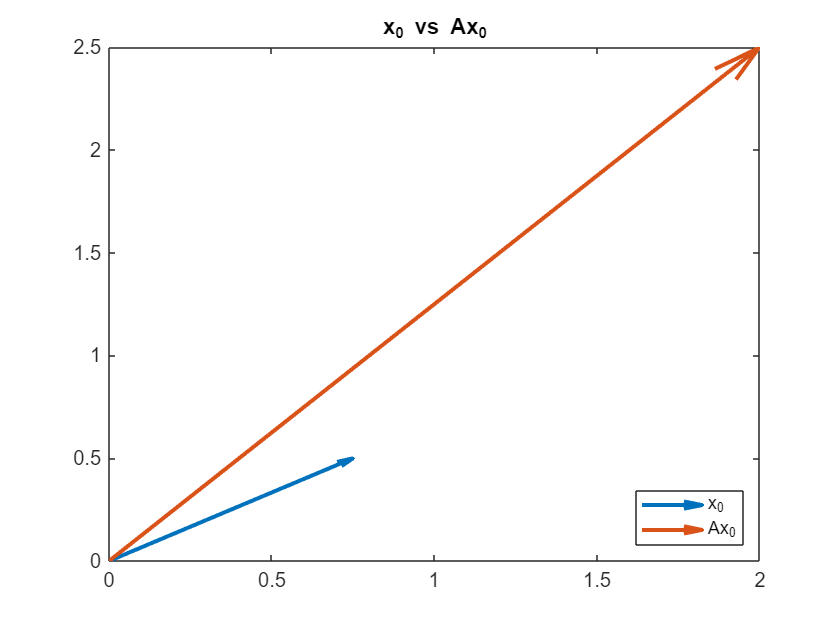

Ax0=A*x0;
quiver(0,0,x0(1,1),x0(2,1),LineWidth=2)
hold on
quiver(0,0,Ax0(1,1),Ax0(2,1),LineWidth=2)
title("x_0 vs Ax_0")
legend("x_0","Ax_0",Location="southeast")
hold off

Now we will plot the resulting vector $x$ or in this case $x_5$ versus $Ax_5$. 

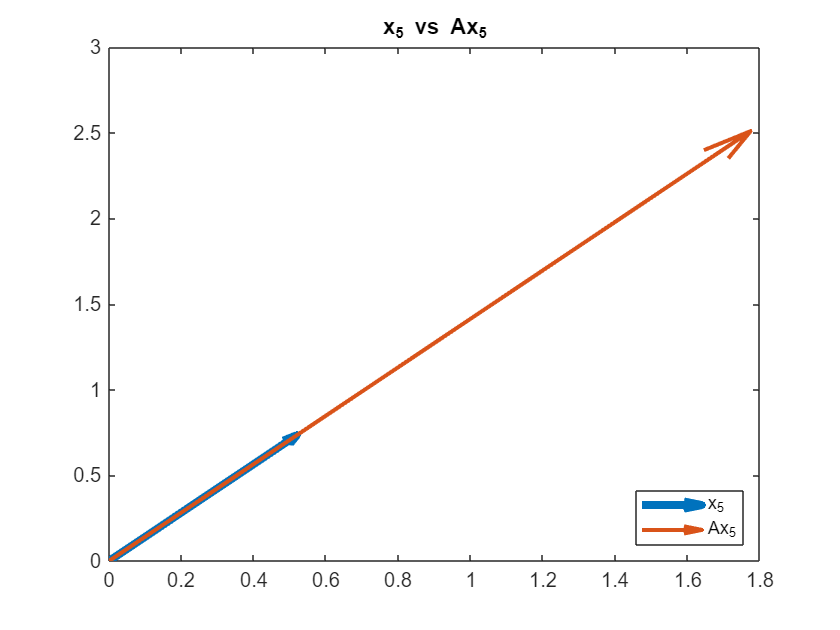

Ax=A*x;
quiver(0,0,x(1,1),x(2,1),LineWidth=4)
hold on
quiver(0,0,Ax(1,1),Ax(2,1),LineWidth=2)
title("x_5 vs Ax_5")
legend('x_5','Ax_5','Location','southeast')
hold off

 **Reflect**.

Notice anything by comparing the two plots? Anything you can say about vector $x_5$? Can you explain the definition of an eigenvector/eigenvalue $\left(\textrm{Ax}=\lambda x\right)$ graphically based on the previous plot? 

Let's now verify that $x_5$ is an eigenvector by using the eig command in MATLAB. Note: check the MathWorks documentation page for [eig](https://www.mathworks.com/help/matlab/ref/eig.html).

[v,d]=eig(A); % v stores the eigenvectors (in columns), d stores the eigenvalues (in the diagonal elements)
v

v =     0.5774   -0.5774
    0.8165    0.8165


x % display the output from the previous power iteration

x =     0.5774
    0.8165


Notice how one of the eigenvectors of $A$ (columns of v) is almost identical to vector x.

Now let's calculate the Rayleigh quotient for $x_5$ and display that alongside the eigenvalues of $A$. Note: check the MathWorks documentation page for [ctranspose](https://www.mathworks.com/help/matlab/ref/double.ctranspose.html).

rayleigh=x'*A*x

rayleigh = 3.4143

d % display the eigenvalues of A for comparison

d =     3.4142         0
         0    0.5858


Notice that one of the diagonal elements of d (dominant eigenvalue) is almost equal to the calculated Rayleigh quotient.

The Rayleigh quotient is a great way to calculate dominant eigenvalues if we have access to the corresponding dominant eigenvector. And by using the power iteration, we are guaranteed to find a dominant eigenvector.

It's an alternative and very simple way of calculating dominant eigenvalues/eigenvectors. The caveat here is that we can't calculate all the eigenvalues but only the dominant (largest/smallest) ones. This may sound like a major limitation but for most engineering and real-life problems it suffices.

## Performance Analysis

Let's explore the same concepts from a performance standpoint. We will compare calculation speed of eigenvalues/eigenvectors for: 

- power iteration 

- the eig MATLAB function 

- the good old characteristic polynomial approach (probably everyone's first contact with the concept of eigenvalue)

We'll test this for a 6x6 matrix. First, let's see how fast power iteration is. Note: check the MathWorks documentation pages for the [tic](https://www.mathworks.com/help/matlab/ref/tic.html) and [toc](https://www.mathworks.com/help/matlab/ref/toc.html) functions.

A=randi(4,6,6);
x=randi(4,6,1);
x=x/norm(x);
n=10;
tic % start the timer
for k=1:n % run the iteration 10 times
    y=A*x;
    x=y/norm(y);
end
rayleigh=x'*A*x;
time_power_iteration=toc % stop the timer

time_power_iteration = 0.0026

tic
[v,d]=eig(A);
time_matlab_eig=toc

time_matlab_eig = 0.0130

v % display the eigenvectors (columns) for validation

v =   -0.3521 + 0.0000i   0.2857 + 0.0000i   0.7029 + 0.0000i   0.7029 + 0.0000i  -0.1560 - 0.1877i  -0.1560 + 0.1877i
  -0.3523 + 0.0000i   0.2784 + 0.0000i  -0.3465 + 0.3064i  -0.3465 - 0.3064i   0.3413 + 0.0390i   0.3413 - 0.0390i
  -0.3677 + 0.0000i   0.2673 + 0.0000i   0.1333 - 0.2461i   0.1333 + 0.2461i   0.3321 - 0.0822i   0.3321 + 0.0822i
  -0.4557 + 0.0000i  -0.5706 + 0.0000i  -0.0195 - 0.3177i  -0.0195 + 0.3177i  -0.7114 + 0.0000i  -0.7114 + 0.0000i
  -0.3815 + 0.0000i  -0.5970 + 0.0000i   0.1056 + 0.1256i   0.1056 - 0.1256i  -0.2209 + 0.0251i  -0.2209 - 0.0251i
  -0.5133 + 0.0000i   0.2956 + 0.0000i  -0.2882 + 0.0491i  -0.2882 - 0.0491i   0.3642 + 0.1314i   0.3642 - 0.1314i


d % display the eigenvalues (diagonal elements)

d =   16.0472 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -1.3669 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5466 + 0.9937i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   1.5466 - 0.9937i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1132 + 0.3295i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1132 - 0.3295i


x % display the output of power iteration (dominant eigenvector)

x =     0.3521
    0.3523
    0.3677
    0.4557
    0.3815
    0.5133


rayleigh % display the rayleigh quotient

rayleigh = 16.0472

Now let's derive the eigenvalues using the characteristic polynomial. Note: check the MathWorks documentation pages for [syms](https://www.mathworks.com/help/symbolic/syms.html), [charpoly](https://www.mathworks.com/help/symbolic/sym.charpoly.html), [solve](https://www.mathworks.com/help/symbolic/sym.solve.html) and [vpa](https://www.mathworks.com/help/symbolic/vpa.html). VPA stands for variable precision arithmetic and it is used to numerically approximate the default, symbolic output of the solve function.

tic
syms x
charpol = charpoly(A,x);
eigenvalues = vpa(solve(charpol),4);
time_char_poly=toc

time_char_poly = 0.9826

eigenvalues

$$eigenvalues = \left(\begin{array}{c} 0.1132+0.3295\,\mathrm{i}\\ 0.1132-0.3295\,\mathrm{i}\\ -1.367\\ 1.547-0.9937\,\mathrm{i}\\ 1.547+0.9937\,\mathrm{i}\\ 16.05 \end{array}\right)$$

 **Reflect**.

Which method was faster? Which one was slower? Remember that with the eig function we are able to calculate all eigenvalues and eigenvectors while the characteristic polynomial method **only** calculates the eigenvalues. Previous findings should give you an idea why numerical linear algebra techniques and algorithms are important for large scale computations.

   **Try**

Write your own code below and test calculation speed for $n>6$. You can use a dropdown menu and experiment with multiple, large values for $n$. A short video on how to integrate live controls in your code can be found [here](https://www.mathworks.com/videos/how-to-use-live-editor-controls-1569868241587.html).

   **Try**

What happens if you try to implement power iteration for the matrix $A=\left\lbrack \begin{array}{cc}
1 & 1\\
0 & 1
\end{array}\right\rbrack$? Justify with a few lines of code below.

## **Further Exploration**

Finding eigenvalues by calculating the characteristic polynomial comes down to finding roots. And polynomial roots can be very sensitive to perturbations (minor changes) in the polynomial coefficients. In real-life applications, it often happens that we don't have 100% accurate parameter estimation and this practically translates to some inaccuracies in the characteristic polynomial coefficients. Therefore, the characteristic polynomial is not very reliable if we want to approximate eigenvalues in a practical scenario.

MathWorks' chief mathematician and co-founder, Cleve Moler, wrote about this in his blog 11 years ago: [Cleve's Corner: Wilkinson's Polynomials](https://blogs.mathworks.com/cleve/2013/03/04/wilkinsons-polynomials/). It's an interesting read if you are willing to dig a little deeper. Specifically in the Wilkinson's perturbation section, he talks about what happens if we change one polynomial coefficient by a tiny little bit ($2^{-k} ,23\le k\le 36$).

## **Practice Problem**

Write code that calculates dominant eigenvalues/eigenvectors with the use of power iteration for a random 6x6 matrix and terminates when $\left|R\left(A,x_k \right)-R\left(A,x_{k-1} \right)\right|\le \varepsilon R\left(A,x_k \right)$ and $\left\|x_k -x_{k-1} \right\|\le \varepsilon$ for an arbitrarily small $\varepsilon$ of your choice. 

-     Test for larger dimensions and multiple values for $\varepsilon$ and confirm it's working properly by comparing the results with the eig function. Comment on the number of iterations we need for the algorithm to converge.

-     Run your code for the inverse matrix $A^{-1}$. Were the outputs expected?

For this practice problem, check MathWorks documentation pages for [abs](https://www.mathworks.com/help/matlab/ref/abs.html), [if](https://www.mathworks.com/help/matlab/ref/if.html), [inv](https://www.mathworks.com/help/matlab/ref/inv.html) and [mldivide](https://www.mathworks.com/help/matlab/ref/double.mldivide.html) (otherwise known as the MATLAB backslash).

  **Pro-tip.**

This script focuses on numerical linear algebra techniques and we'd like to close with a pro tip. You are probably wondering what's with the mldivide function? Mldivide (or backslash) is used to solve a linear system $\textrm{Ax}=B$ and it's one of our flagship functions, because it's fast and efficient. There's a way to use the backslash ($x=A\backslash B$) and calculate the inverse of a matrix. That part is left to you as a short exercise. You can use the inv function for the practice problem above if you so wish, but our recommendation is to make use of the backslash.